%Assignment 2)
%Question 1 a)
clear %clearing any stored variables/plots

%declaring imaginary numbers
%sym used so that answers are more readable
ZL = sym(16 + 1i*0);
ZT = sym(.1 + 1i*0.4);

%calculating numerators & denominators
Num = ZL - ZT;
Den = ZL + ZT;

%calculating gamma
GL = simplify(ZL - ZT)/(ZL + ZT)

$$GL = \frac{25583}{25937}-\frac{1280}{25937}\,\mathrm{i}$$

eval(GL)

ans = 0.9864 - 0.0494i


%checking gamma calculation
eval((Num*conj(Den)) / (Den*conj(Den)))

ans = 0.9864 - 0.0494i


%Question 1 b)
%extracting required values from previously calcualted coefficient gamma
eval(abs(GL)) %extracting absolute 

ans = 0.9876

eval(angle(GL)) %extracting angle 

ans = -0.0500

%Question 2)
clear %clearing any stored variables/plots
syms s %declaring symbolic variables

eqn = s^4 == -625; %declaring equation

sol = solve(eqn,s) %solving equation

$$sol = \left(\begin{array}{c} \sqrt{2}\,\left(-\frac{5}{2}-\frac{5}{2}\,\mathrm{i}\right)\\ \sqrt{2}\,\left(-\frac{5}{2}+\frac{5}{2}\,\mathrm{i}\right)\\ \sqrt{2}\,\left(\frac{5}{2}-\frac{5}{2}\,\mathrm{i}\right)\\ \sqrt{2}\,\left(\frac{5}{2}+\frac{5}{2}\,\mathrm{i}\right) \end{array}\right)$$


%printing solitions in polar
abs(sol(1))

$$ans = 5$$

angle(sol(1))

$$ans = -\frac{3\,\pi }{4}$$

abs(sol(2))

$$ans = 5$$

angle(sol(2))

$$ans = \frac{3\,\pi }{4}$$

abs(sol(3))

$$ans = 5$$

angle(sol(3))

$$ans = -\frac{\pi }{4}$$

abs(sol(4))

$$ans = 5$$

angle(sol(4))

$$ans = \frac{\pi }{4}$$

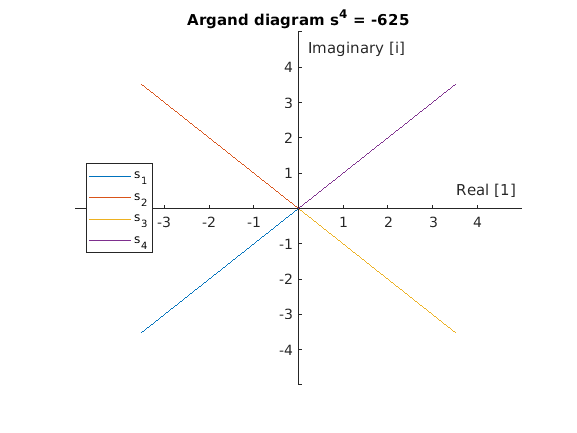


%plotting argand diagram (connected to origin)
plot([0 real(sol(1))],[0 imag(sol(1))]) %plotting first point 
hold on %plotting on same graph
plot([0 real(sol(2))],[0 imag(sol(2))]) %plotting second point 
hold on %plotting on same graph
plot([0 real(sol(3))],[0 imag(sol(3))]) %plotting third point 
hold on %plotting on same graph
plot([0 real(sol(4))],[0 imag(sol(4))]) %plotting fourth point 
hold on %plotting on same graph

hold off %making sure it doesnt go over to next question

%beautifying plot
ax = gca;
ax.XAxisLocation ="origin";
ax.YAxisLocation ="origin";
box off %because Patrick doesn't like boxes

%setting limits
xlim([-5 5])
ylim ([-5 5])

%labelling graph
xlabel("Real [1]")
ylabel("Imaginary [i]")
title("Argand diagram s^{4} = -625")
legend("s_1","s_2","s_3","s_4","location","west")
xticks([-4 -3 -2 -1 0 1 2 3 4]); %Xaxis values werent't showing

%Question 3)
clear %clearing any stored variables/plots

%declaring matrices
A = sym([ ...
    1 0 0 0 0;
    1 0.5 0.25 0.125 0.0625;
    1 1 1 1 1;
    1 1.5 2.25 3.375 5.0625;
    1 2 4 8 16
    ]);

B = sym([ ...
    0;
    0.06473;
    0.43826;
    0.69750;
    0.34342
    ]);

%Calculating inverse of A
inv(A)

$$ans = \left(\begin{array}{ccccc} 1 & 0 & 0 & 0 & 0\\ -\frac{25}{6} & 8 & -6 & \frac{8}{3} & -\frac{1}{2}\\ \frac{35}{6} & -\frac{52}{3} & 19 & -\frac{28}{3} & \frac{11}{6}\\ -\frac{10}{3} & 12 & -16 & \frac{28}{3} & -2\\ \frac{2}{3} & -\frac{8}{3} & 4 & -\frac{8}{3} & \frac{2}{3} \end{array}\right)$$


%Calculating X
X = inv(A)*B

$$X = \left(\begin{array}{c} 0\\ -\frac{42343}{100000}\\ \frac{397367}{300000}\\ -\frac{5153}{12500}\\ -\frac{3797}{75000} \end{array}\right)$$

eval(X)

ans =          0
   -0.4234
    1.3246
   -0.4122
   -0.0506



%%checking function goes through points
%plotting known coordinates:
xcoord = [0 0.5 1 1.5 2]; %x coordinates to plot

%corresponding bessel function y points
ycoord = [0 0.06473 0.43826 0.69750 0.34342]; 
plot(xcoord, ycoord, ".r")

hold on %ensuring plot remains on same graph

%declaring function to plot
syms S(x)
S(x) = X(1) + x*X(2) + x^2*X(3) + x^3*X(4) + x^4*X(5)

$$S(x) = -\frac{3797\,x^{4}}{75000}-\frac{5153\,x^{3}}{12500}+\frac{397367\,x^{2}}{300000}-\frac{42343\,x}{100000}$$

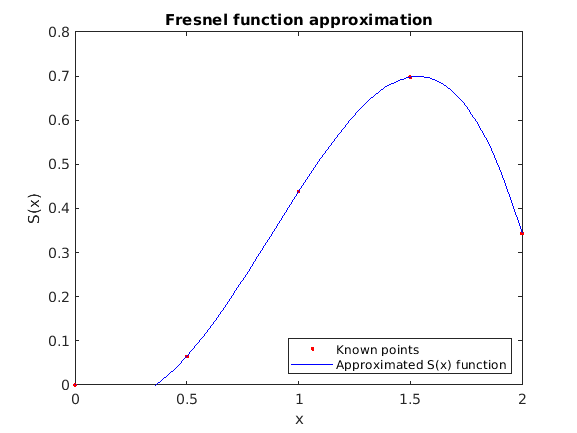


%plotting 
fplot(S(x),"b")
ylim([0 0.8])
xlim([0 2])
hold off

%beautiying curve
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";

%labelling graph
xlabel("x")
ylabel("S(x)")
title("Fresnel function approximation")
legend("Known points","Approximated S(x) function","Location","southeast")


%checking coordinates work in new equation
eval(S(xcoord(1)))

ans = 0

eval(S(xcoord(2)))

ans = 0.0647

eval(S(xcoord(3)))

ans = 0.4383

eval(S(xcoord(4)))

ans = 0.6975

eval(S(xcoord(5)))

ans = 0.3434

%Question 4
clear all %clearing any stored variables/plots
syms O(t) k F_1(t) F_2(t) %declaring symbolic variables
ode = diff(O,t) == -k*(O-20) %declaring ODE where O is theta

$$ode(t) = \frac{\partial }{\partial t}\text{O}\left(t\right)=-k\,\left(\text{O}\left(t\right)-20\right)$$

init_cond = O(0) == 100 %declaring initial conditions

$$init\_cond = \text{O}\left(0\right)=100$$

O = dsolve(ode,init_cond) %finding particular solution for ODE

$$O = 80\,{\mathrm{e}}^{-k\,t}+20$$



%declaring function to plot
F_1(t) = 80*exp(-0.025*t)+20 %k=0.025

$$F\_1(t) = 80\,{\mathrm{e}}^{-\frac{t}{40}}+20$$

F_2(t) = 80*exp(-0.05*t)+20 %k=0.05

$$F\_2(t) = 80\,{\mathrm{e}}^{-\frac{t}{20}}+20$$

F_3(t) = 80*exp(-0.1*t)+20 %k=0.1

$$F\_3(t) = 80\,{\mathrm{e}}^{-\frac{t}{10}}+20$$

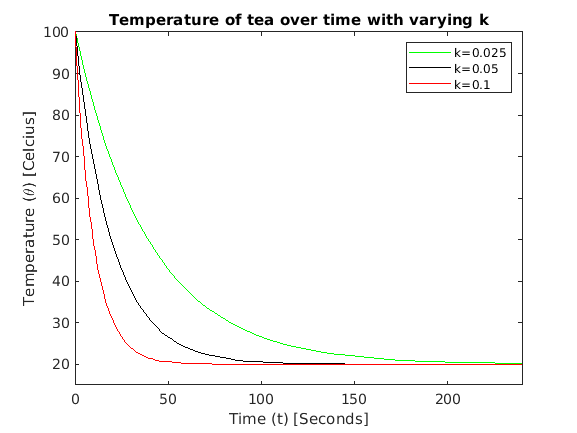


assume (t>=0) %sensible assumption about time

%plotting both decays on same graph
fplot(F_1,"g")
hold on
fplot(F_2,"k")
hold on
fplot(F_3,"r")
hold off

%setting limits
ylim([15 100])
xlim([0 240 ])

%beautiying curve
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";

%labelling graph
xlabel("Time (t) [Seconds]")
ylabel("Temperature (\theta) [Celcius]")
title("Temperature of tea over time with varying k")
legend("k=0.025","k=0.05","k=0.1","Location","northeast")